[~,p] = fit_logistic(time_E3,OD3)

p =   372.6930    1.2743    0.0093


t = 0:1200;
q = p(2)./(1+exp(-p(3)*(t-p(1))));
b = bar(time_E3, smell3, 'y')

b =   Bar with properties:

    BarLayout: 'grouped'
     BarWidth: 0.8000
    FaceColor: [1 1 0]
    EdgeColor: [0 0 0]
    BaseValue: 0
        XData: [0 21.0000 43.0000 462.0000 473 484.0000 495.0000 506.0000 866.0000 879.0000 891 902 914 929 1094 1133 1143]
        YData: [0 0 0 1.6667 2 1 0.6667 0 0.6667 0.6667 0.6667 1 0.6667 1 0.5000 1 1]

  Show all properties


hold on
plot(t,q,'k');
plot(time_E3, OD3,'*','MarkerSize', 5,'MarkerEdgeColor','red');
xlabel('Time (min)')    
ylabel('OD600')
s=findobj('tag', 'legend')

s =   0×0 empty GraphicsPlaceholder array.


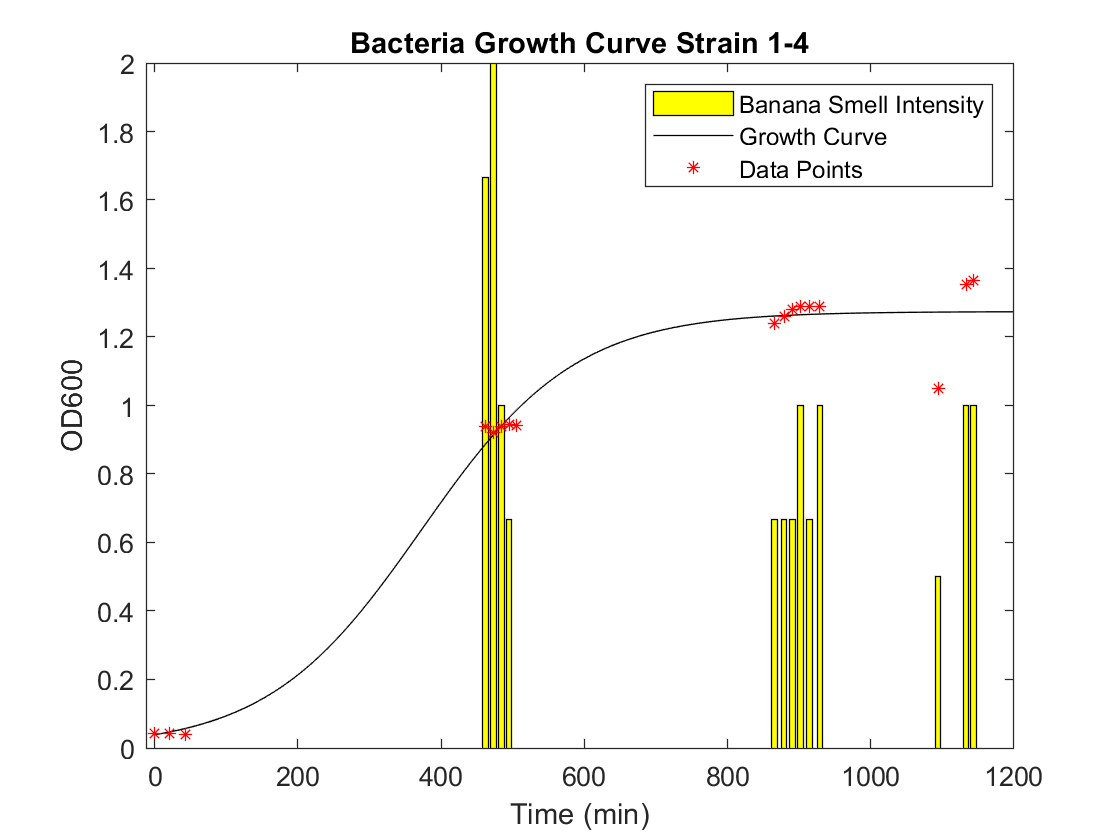


title('Bacteria Growth Curve Strain 1-4')

legend('Banana Smell Intensity','Growth Curve', 'Data Points')